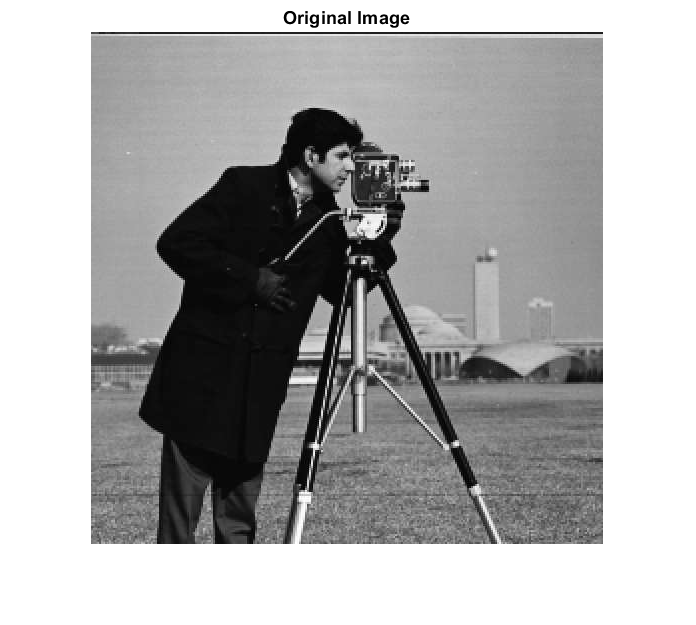

clear all;
close all;
clc;

img = imread('cameraman.jpg');
imshow(img);
title('Original Image');

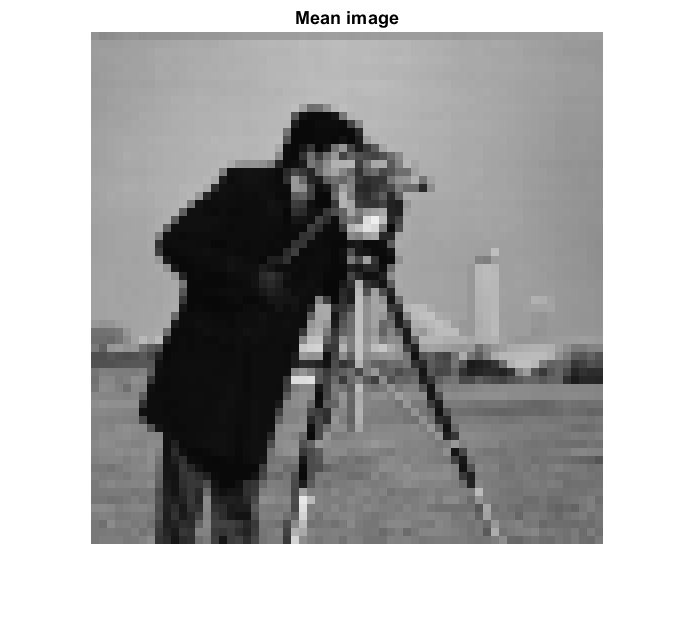

fun_mean = @(block_struct)mean2(block_struct.data) *...
    ones(size(block_struct.data));
mean_img_double = blockproc(img, [8 8], fun_mean);
imshow(uint8(mean_img_double));
title('Mean image');

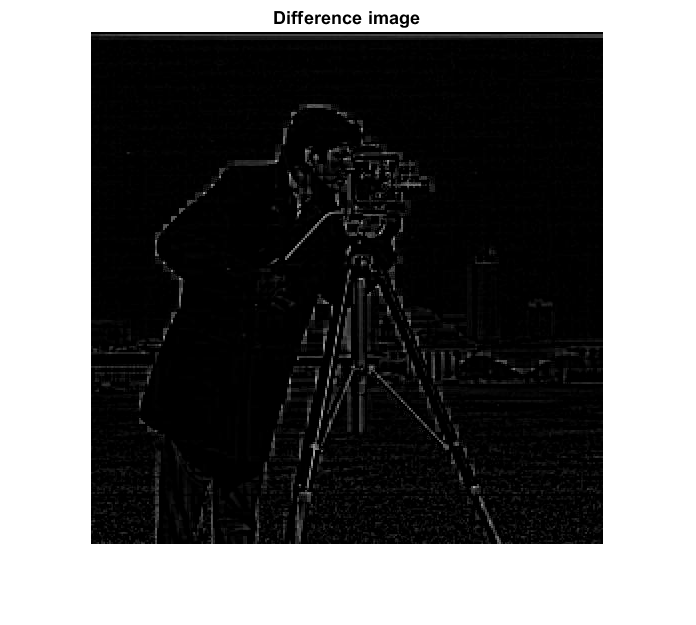

diff_img_uint8 = uint8(double(img) - mean_img_double);
imshow(diff_img_uint8);
title('Difference image');

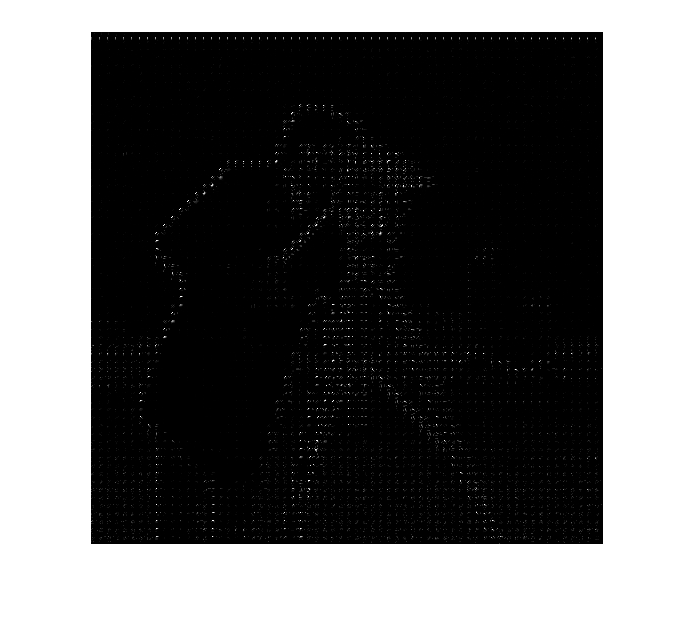

% DCT coefficients for diff image.
fun_dct = @(block_struct)dct2(block_struct.data);
dct_coefficient_diff =  blockproc((double(img)-mean_img_double), [8 8], fun_dct);
imshow(uint8(dct_coefficient_diff));

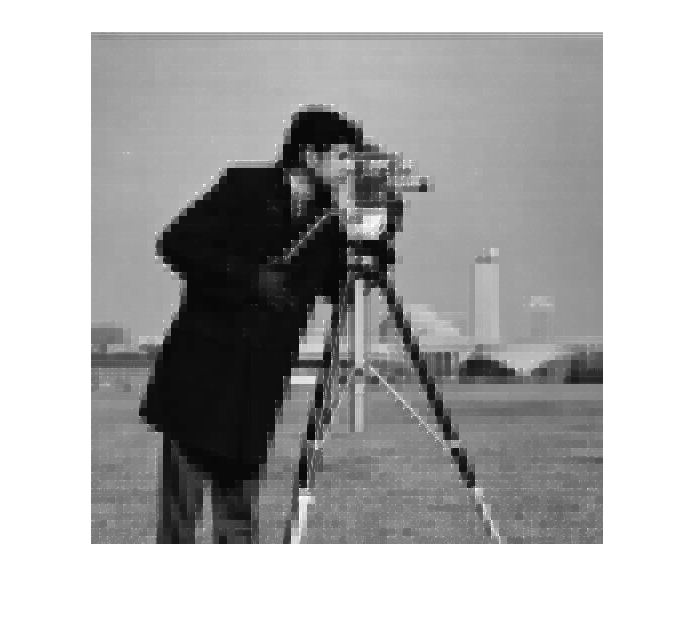


[zipped_mean, zipped_diff, info_mean, info_diff] = jpeg_lite(img);
%----------------------------------------
% After doing the encoding and try to decode:
img_recover = jpeg_lite_decoder(zipped_mean, zipped_diff, info_mean, info_diff);
imshow(img_recover);

title('Recovered image');
peaksnr = psnr(img_recover, img)

peaksnr = 22.0387



% Compared with directly encoding the diff image, does encoding the DCT of
% the diff image gives better coding efficiency? 